# Setup

clc
clear
warning('off')

%Get Current directory
mlxpath = DirectoryHandler;

%Input signals

%Position Input
N_temp = 534; %TODO: Increase time to match Land (issues with stitching chirp)
delta_t = 0.01;
t = 0:delta_t:2*N_temp*delta_t;
NT = 2*N_temp;
t1 = 0:delta_t:N_temp*delta_t;
I_p(1:N_temp+1) = -chirp(t1,0.5,N_temp*delta_t,1)+1;
I_p(N_temp+1:2*N_temp+1) = -chirp(t1,1,N_temp*delta_t,3)+1;

%Velocity Input
I_v = diff(I_p)/delta_t;

%Time Alignment
I_p = I_p(1:NT);
t = t(1:NT);

%Concatenate Time Series
P_in = [t;I_p]';
V_in = [t;I_v]';

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'CombinedModel';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

# Figure A: Low Gain Smooth with only Position feedback

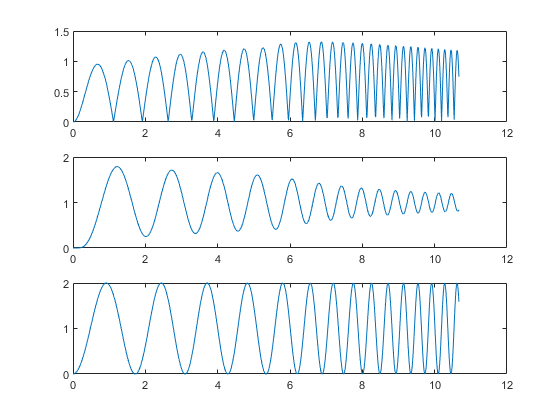

%Set simulation parameters for scenario A

%Gains
PSM = 3;
VSM = 0;
VSA = 0;
PSA = 0;

%Delay and zero-order hold time
PSM_delay = 0.1;
VSM_delay = 0.1;
PSA_delay = 0.1;
VSA_delay = 0.1;
zohTime = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
a_pout = out.P_out;
a_vout = out.V_out;

%Position Error
a_error = abs(a_pout-P_in(:,2));


figure
subplot(3,1,1)
plot(t,a_error)
subplot(3,1,2)
plot(t,a_pout)
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))

# Figure B: Low Gain Smooth with only Velocity feedback

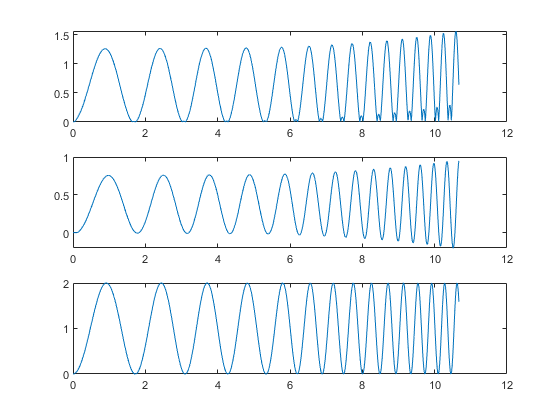

%Set simulation parameters for scenario B

%Gains
PSM = 0;
VSM = 0.6;
VSA = 0;
PSA = 0;

%Delay and zero-order hold time
PSM_delay = 0.1;
VSM_delay = 0.1;
PSA_delay = 0.1;
VSA_delay = 0.1;
zohTime = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
b_pout = out.P_out;
b_vout = out.V_out;

%Position Error
b_error = abs(b_pout-P_in(:,2));

%Figure
figure
subplot(3,1,1)
plot(t,b_error)
subplot(3,1,2)
plot(t,b_pout)
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))

# Figure C: High Gain Smooth with only Position feedback

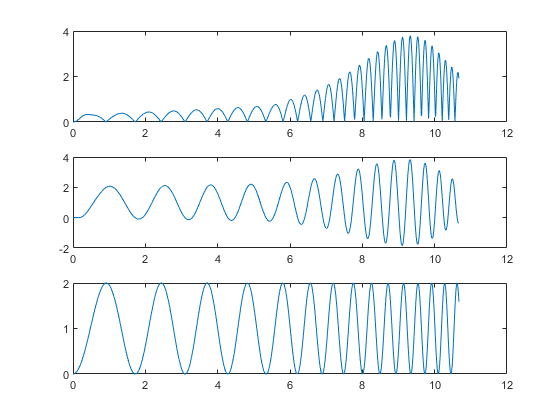

%Set simulation parameters for scenario C

%Gains
PSM = 11;
VSM = 0;
VSA = 0;
PSA = 0;

%Delay and zero-order hold time
PSM_delay = 0.1;
VSM_delay = 0.1;
PSA_delay = 0.1;
VSA_delay = 0.1;
zohTime = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
c_pout = out.P_out;
c_vout = out.V_out;

%Position Error
c_error = abs(c_pout-P_in(:,2));

%Figure
figure
subplot(3,1,1)
plot(t,c_error)
subplot(3,1,2)
plot(t,c_pout)
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))

# Figure D: Smooth with both position and velocity feedback

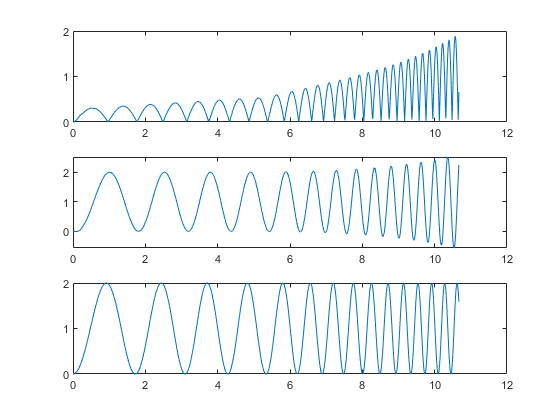

%Set simulation parameters for scenario D

%Gains
PSM = 11;
VSM = 0.6;
VSA = 0;
PSA = 0;

%Delay and zero-order hold time
PSM_delay = 0.1;
VSM_delay = 0.1;
PSA_delay = 0.1;
VSA_delay = 0.1;
zohTime = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
d_pout = out.P_out;
d_vout = out.V_out;

%Position Error
d_error = abs(d_pout-P_in(:,2));

%Figure
figure
subplot(3,1,1)
plot(t,d_error)
subplot(3,1,2)
plot(t,d_pout)
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))

# Figure E: Saccadic with position only

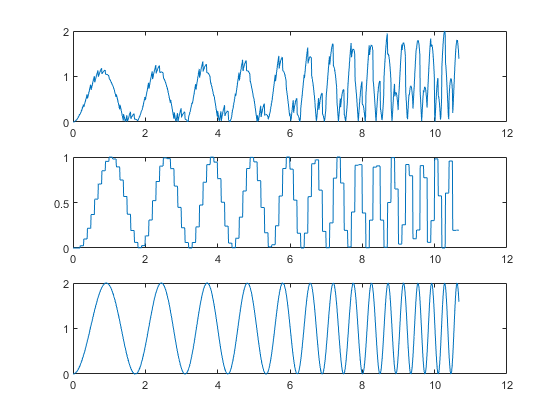

%Set simulation parameters for scenario E

%Gains
PSM = 0;
VSM = 0;
VSA = 0;
PSA = 1;

%Delay and zero-order hold time
PSM_delay = 0.1;
VSM_delay = 0.1;
PSA_delay = 0.1;
VSA_delay = 0.1;
zohTime = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
e_pout = out.P_out;
e_vout = out.V_out;

%Position Error
e_error = abs(e_pout-P_in(:,2));

%Figure
figure
subplot(3,1,1)
plot(t,e_error)
subplot(3,1,2)
plot(t,e_pout)
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))

# Figure F: Saccadic with position and velocity

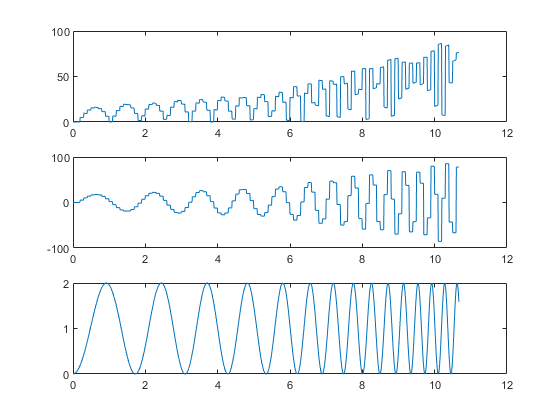

%Set simulation parameters for scenario F

%Gains
PSM = 0;
VSM = 0;
VSA = 10;
PSA = 1;

%Delay and zero-order hold time
PSM_delay = 0.1;
VSM_delay = 0.1;
PSA_delay = 0.1;
VSA_delay = 0.1;
zohTime = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
f_pout = out.P_out;
f_vout = out.V_out;

%Position Error
f_error = abs(f_pout-P_in(:,2));

%Figure
figure
subplot(3,1,1)
plot(t,f_error)
subplot(3,1,2)
plot(t,f_pout)
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))

# Figure G: Saccadic with position and velocity + smooth velocity feedback

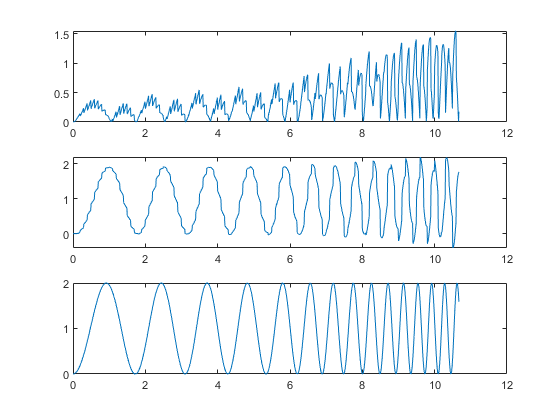

%Set simulation parameters for scenario G

%Gains
PSM = 0;
VSM = 0.8;
VSA = 0.05; %TODO: Why does Land use 5? In this sim, that kills the continuous leg
PSA = 1;

%Delay and zero-order hold time
PSM_delay = 0.1;
VSM_delay = 0.1;
PSA_delay = 0.1;
VSA_delay = 0.1;
zohTime = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = inf;
VSM_sat_low = -inf;

%Simulate

out = sim('combinedModel.slx');

%Outputs
g_pout = out.P_out;
g_vout = out.V_out;

%Position Error
g_error = abs(g_pout-P_in(:,2));

%Figure
figure
subplot(3,1,1)
plot(t,g_error)
subplot(3,1,2)
plot(t,g_pout)
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))

# Figure H: Saccadic with position and velocity + smooth velocity feedback w/ thresholding

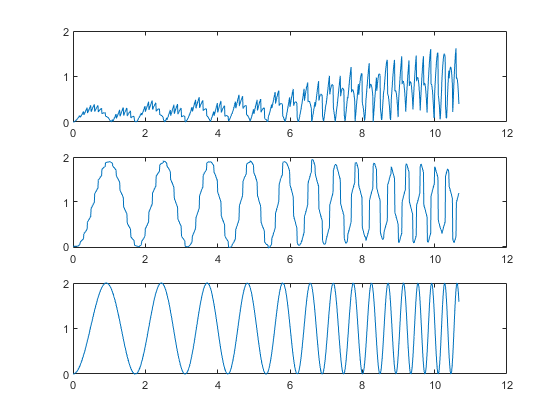

%Set simulation parameters for scenario G

%Gains
PSM = 0;
VSM = 0.8;
VSA = 0.05; %TODO: Why does Land use 5? In this sim, that kills the continuous leg
PSA = 1;

%Delay and zero-order hold time
PSM_delay = 0.1;
VSM_delay = 0.1;
PSA_delay = 0.1;
VSA_delay = 0.1;
zohTime = 0.1;

%Saturation Levels
PSA_sat_up = inf;
PSA_sat_low = -inf;
VSA_sat_up = inf;
VSA_sat_low = -inf;
PSM_sat_up = inf;
PSM_sat_low = -inf;
VSM_sat_up = 3; %TODO: Land uses 0.3
VSM_sat_low = -3;

%Simulate

out = sim('combinedModel.slx');

%Outputs
h_pout = out.P_out;
h_vout = out.V_out;

%Position Error
h_error = abs(h_pout-P_in(:,2));

%Figure
figure
subplot(3,1,1)
plot(t,h_error)
subplot(3,1,2)
plot(t,h_pout)
subplot(3,1,3)
plot(P_in(:,1),P_in(:,2))